# Getting Started with Logicle Transform  

## Description

A toolbox to apply the logicle transformation to a matrix and provide axes labels.

## System Requirements

MATLAB. No other requirements.

## Features

Transform data by logicle transform, inverse logicle transform and label axes.

## Examples

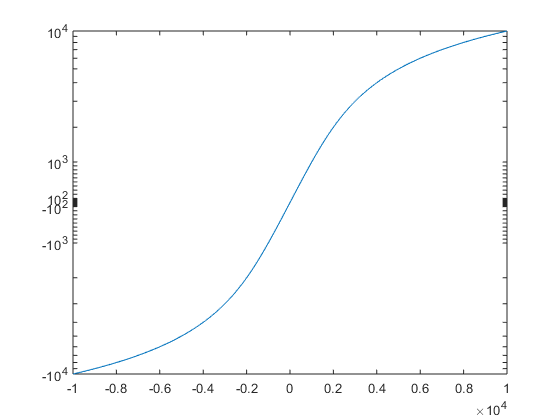

%% Transform a linearly spaced vector
% Create a scalar object, and call the transform method
obj = logicleTransform(10000,2,4,0);
x = linspace(obj.inverse(0),obj.T,1000);
y = obj.transform(x);
plot(x,y);
ax = gca;
ax.YTick = obj.Tick;
ax.YTickLabel = obj.TickLabel;

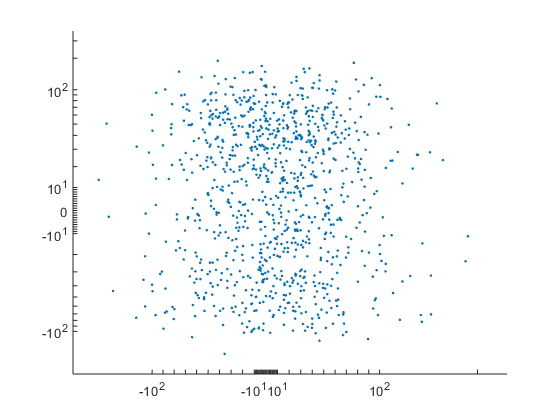

%% Transform a matrix onto two differently transformed axes
% Create a length 2 vector of logicleTransform objects, and transform a
% matrix with two columns onlto the two axes
rng default; % for reproducability
obj = [logicleTransform(1000,2,4,0),logicleTransform(10000,1,4.5,0.4,2^6)];
x = randn(1000,2)*50 + 10;
y = obj.transform(x);
scatter(y(:,1),y(:,2),'.');
ax = gca;
ax.XTick = obj(1).Tick;
ax.XTickLabel = obj(1).TickLabel;
ax.YTick = obj(2).Tick;
ax.YTickLabel = obj(2).TickLabel;